# Homework 7: Use Experiment 1 data only

## Loading Data

% Define the folder containing the .mat files
folderPath = '/Users/giulianabilbao/Desktop/BCI Lab/Lab_8'; % Replace with the path to the folder containing your files

% Get a list of all .mat files in the folder
fileList = dir(fullfile(folderPath, '*.mat'));

% Initialize a structure to store the loaded data
loadedData = struct();

% Loop through each file and load the data
for i = 1:length(fileList)
    % Get the file name
    fileName = fileList(i).name;
    
    % Generate the full file path
    filePath = fullfile(folderPath, fileName);
    
    % Load the data from the .mat file
    loadedData.(matlab.lang.makeValidName(fileName)) = load(filePath);
    
    % Display a message
    fprintf('Loaded file: %s\n', fileName);
end

Loaded file: Lab7_group5_p1_attend_both.mat
Loaded file: Lab7_group5_p1_attend_left.mat
Loaded file: Lab7_group5_p1_attend_none.mat
Loaded file: Lab7_group5_p1_attend_right.mat
Loaded file: Lab7_group5_p2_35hz_1031.mat
Loaded file: Lab7_group5_p2_35hz_1107.mat
Loaded file: Lab7_group5_p2_40hz.mat
Loaded file: Lab7_group5_p3.mat



% Display completion message
disp('All .mat files loaded successfully.');

All .mat files loaded successfully.


## Question 1: Plot the time waveform of the sounds used in your experiments (only the first 100ms of the signal, separately for the left ear and the right ear) and their time-frequency decomposition called a spectrogram (use specgram function in MATLAB). (1 pt)

- I assume experiment 1 sounds only

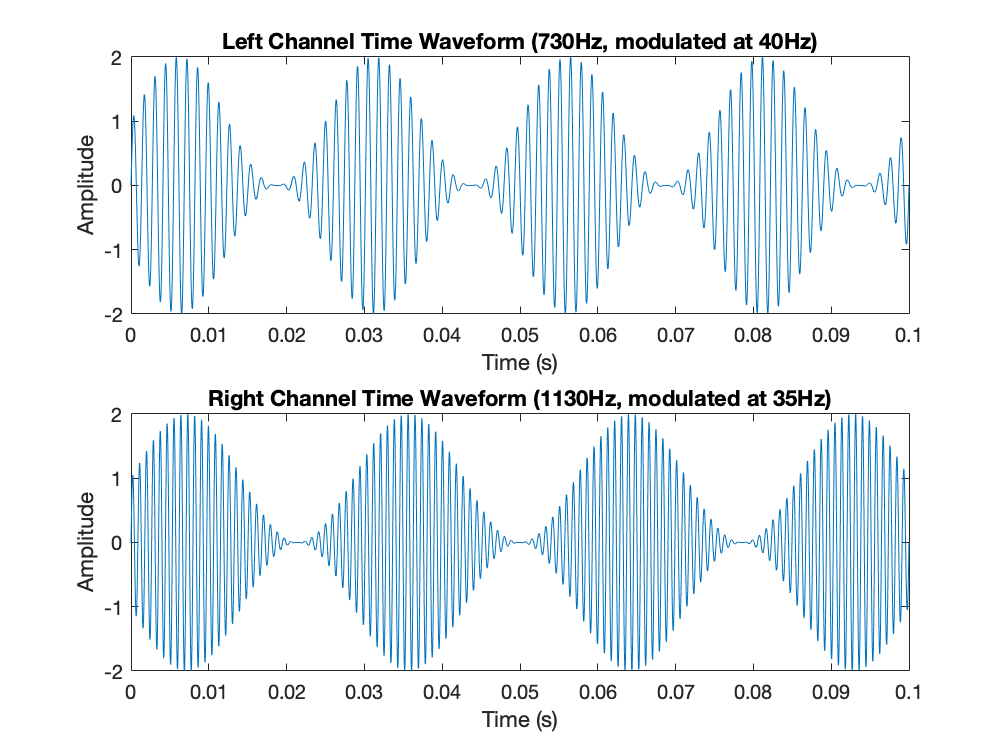


% Parameters
fs = 100000; % Sampling rate in Hz
t = 0:1/fs:0.1; % Time vector for 100ms (0.1 seconds)

% Left channel: 730Hz tone modulated at 40Hz
freq_left = 730; 
mod_left = 40;
left_signal = sin(2*pi*freq_left.*t) .* (1 + sin(2*pi*mod_left.*t));

% Right channel: 1130Hz tone modulated at 35Hz
freq_right = 1130; 
mod_right = 35;
right_signal = sin(2*pi*freq_right.*t) .* (1 + sin(2*pi*mod_right.*t));

% Plot time waveforms
figure;

% Left channel waveform
subplot(2, 1, 1);
plot(t, left_signal);
title('Left Channel Time Waveform (730Hz, modulated at 40Hz)');
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0 0.1]);

% Right channel waveform
subplot(2, 1, 2);
plot(t, right_signal);
title('Right Channel Time Waveform (1130Hz, modulated at 35Hz)');
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0 0.1]);

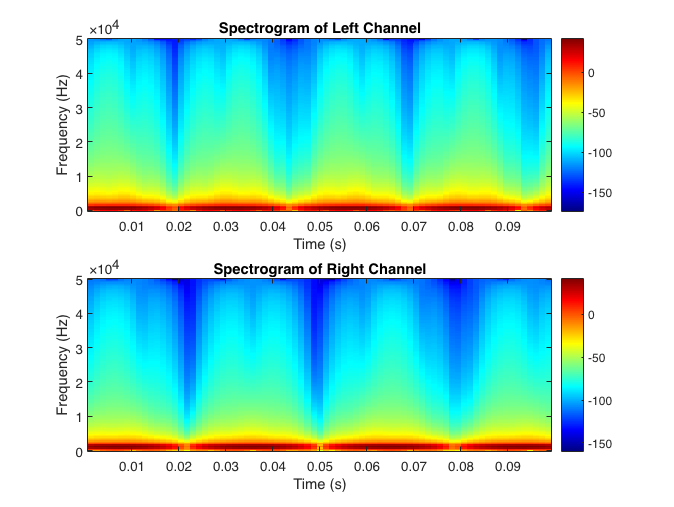


% Plot spectrograms
figure;

% Left channel spectrogram
subplot(2, 1, 1);
specgram(left_signal, 256, fs); % Specgram function
title('Spectrogram of Left Channel');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
colorbar;

% Right channel spectrogram
subplot(2, 1, 2);
specgram(right_signal, 256, fs); % Specgram function
title('Spectrogram of Right Channel');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
colorbar;

## Question 2: Load the EEG signal in Matlab. Use the trigger signal from the s-function to separate the EEG response to sound. (1 pt)

- Trying from 100 to 300

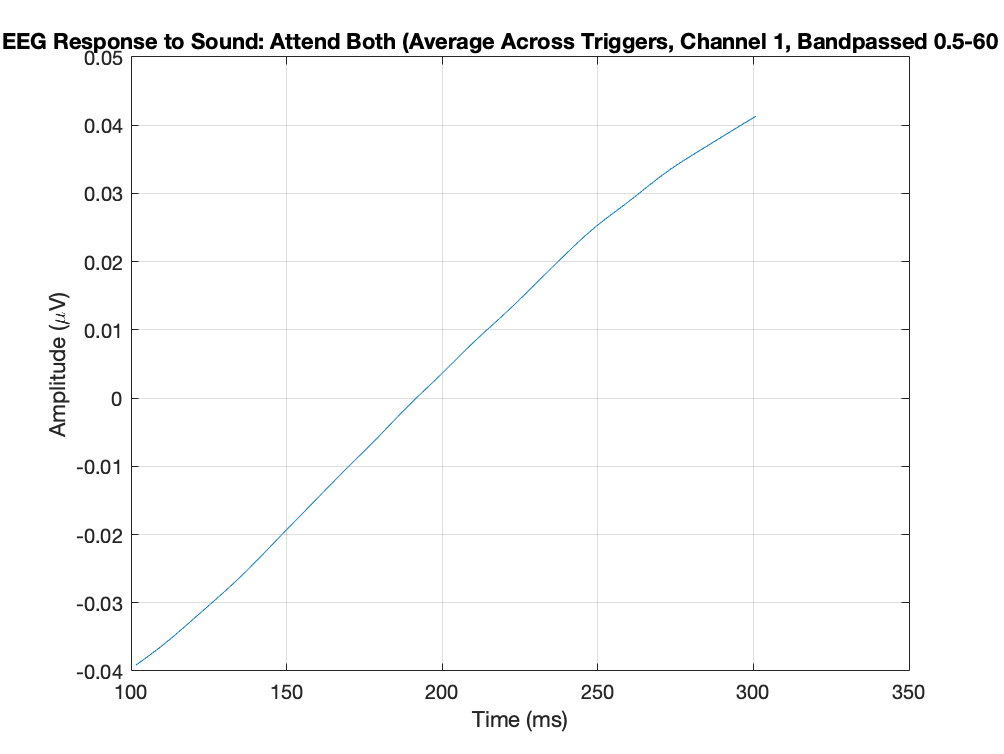

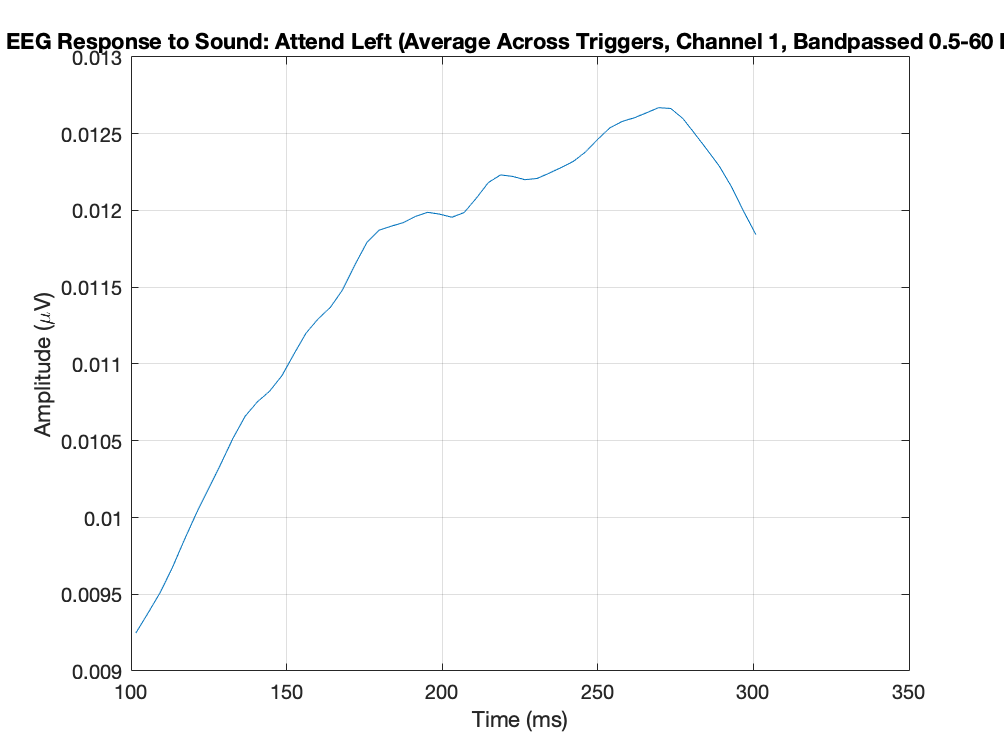

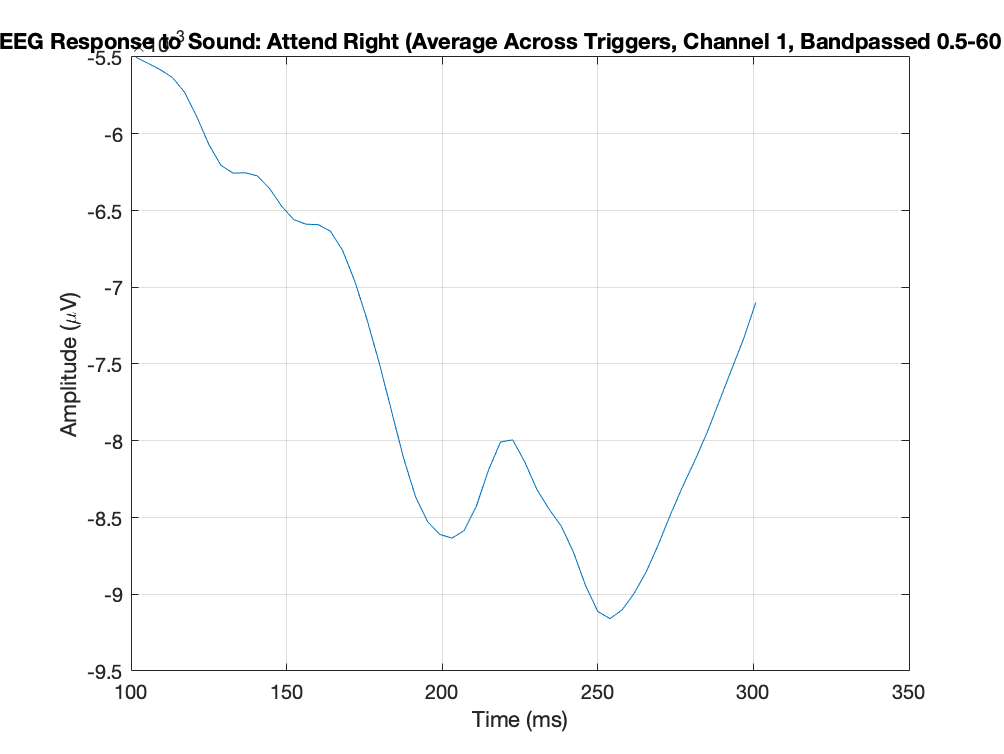

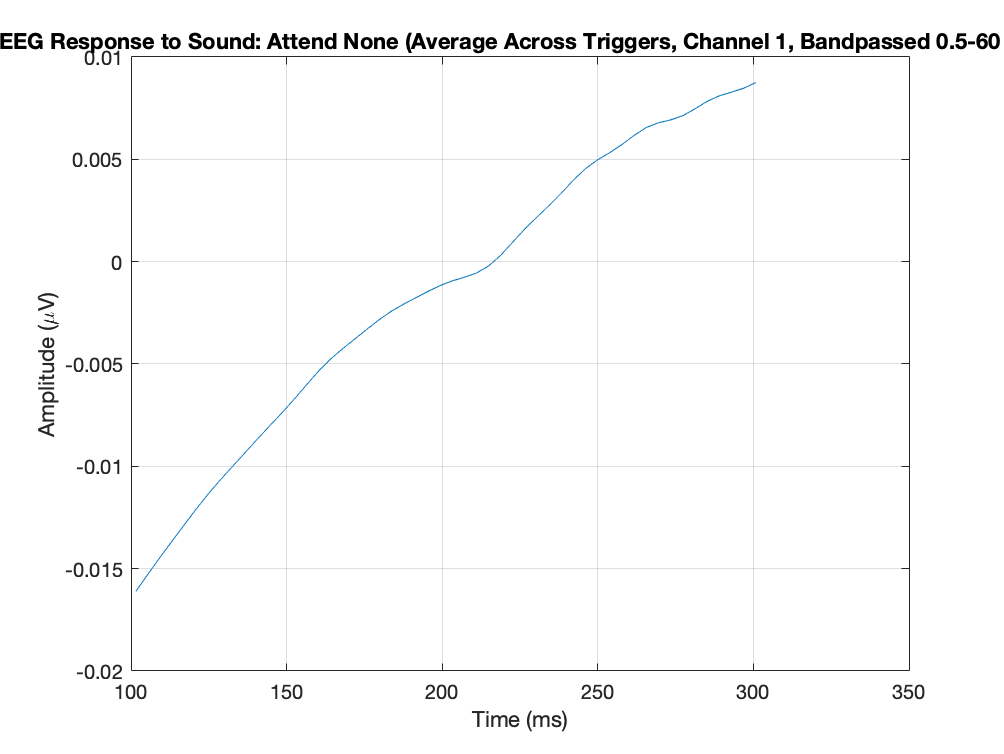


% Sampling rate and time settings
fs = 256; % Sampling rate in Hz
pre_time = 100; % Pre-trigger time in ms
post_time = 300; % Post-trigger time in ms
pre_samples = round(pre_time / 1000 * fs); % Convert to samples
post_samples = round(post_time / 1000 * fs); % Convert to samples

% Bandpass filter range
bandpass_range = [.5 60]; % Isolate the modulation frequencies
eeg_data(ch, :) = bandpass(eeg_data(ch, :), bandpass_range, fs);

% Conditions to process
conditions = {'Lab7_group5_p1_attend_both_mat', 'Lab7_group5_p1_attend_left_mat', ...
              'Lab7_group5_p1_attend_right_mat', 'Lab7_group5_p1_attend_none_mat'};
titles = {'EEG Response to Sound: Attend Both', 'EEG Response to Sound: Attend Left', ...
          'EEG Response to Sound: Attend Right', 'EEG Response to Sound: Attend None'};

% Loop through each condition
for cond_idx = 1:length(conditions)
    % Load the data matrix for the current condition
    data_matrix = loadedData.(conditions{cond_idx}).ans;
    
    % Extract EEG channels (e.g., rows 2 to 8)
    eeg_data = data_matrix(2:8, :);

    % Apply bandpass filter to EEG data
    for ch = 1:size(eeg_data, 1)
        eeg_data(ch, :) = bandpass(eeg_data(ch, :), bandpass_range, fs);
    end

    % Extract trigger signal (last row)
    trigger_signal = data_matrix(end, :);

    % Find trigger indices (where trigger signal fires)
    trigger_indices = find(trigger_signal > 0); % Adjust threshold if needed

    % Initialize a matrix to store EEG segments
    n_triggers = length(trigger_indices);
    n_channels = size(eeg_data, 1);
    segment_length = post_samples - pre_samples + 1;
    eeg_segments = zeros(n_triggers, n_channels, segment_length);

    % Extract EEG segments for each trigger
    for i = 1:n_triggers
        trigger_index = trigger_indices(i);
        segment_start = trigger_index + pre_samples;
        segment_end = trigger_index + post_samples;

        % Ensure indices are within bounds
        if segment_start > 0 && segment_end <= size(eeg_data, 2)
            eeg_segments(i, :, :) = eeg_data(:, segment_start:segment_end);
        end
    end

    % Compute average response across triggers
    average_response = squeeze(mean(eeg_segments, 1)); % Average across trials

    % Time vector for plotting
    time_vector = (pre_samples:post_samples) / fs * 1000; % Time in ms

    % Plot average response for the first channel
    figure;
    plot(time_vector, average_response(1, :)); % Channel 1
    title([titles{cond_idx}, ' (Average Across Triggers, Channel 1, Bandpassed 0.5-60 Hz)']);
    xlabel('Time (ms)');
    ylabel('Amplitude (\muV)');
    grid on;
end

## Question 3: Take the Fourier transform of each channel, and then average the magnitude of FFT over all channels. (1 pt)

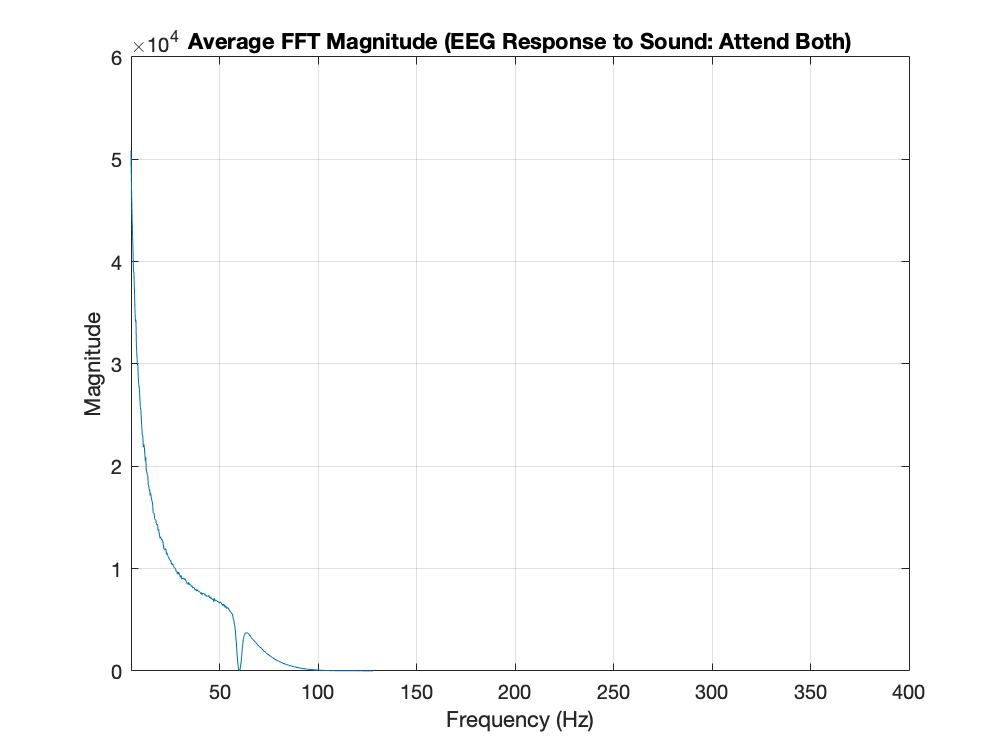

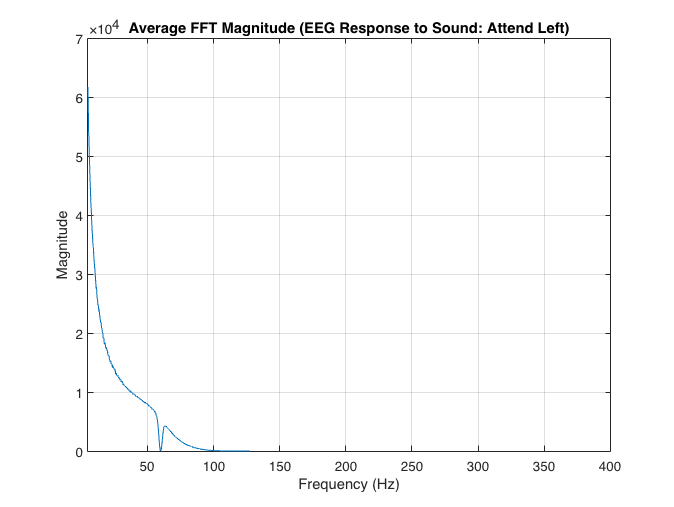

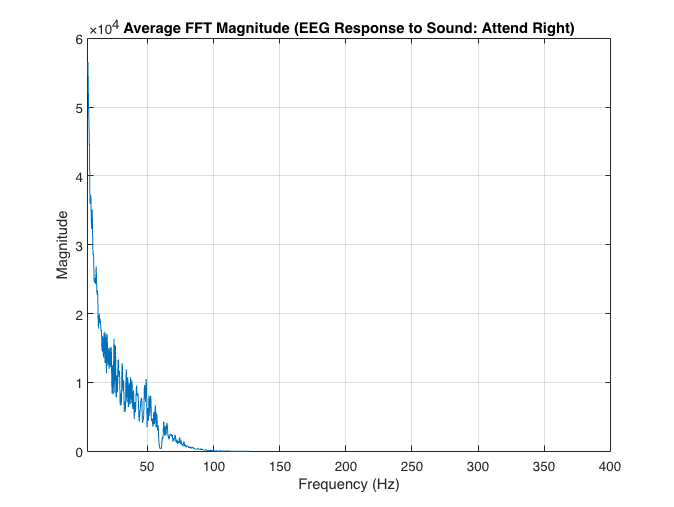

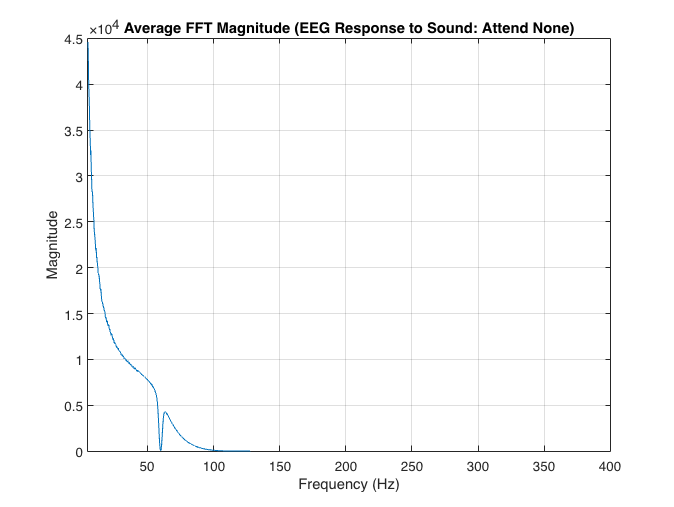

% Sampling rate
fs = 256; % in Hz

% Conditions to process
conditions = {'Lab7_group5_p1_attend_both_mat', 'Lab7_group5_p1_attend_left_mat', 'Lab7_group5_p1_attend_right_mat','Lab7_group5_p1_attend_none_mat'};
titles = {'EEG Response to Sound: Attend Both', 'EEG Response to Sound: Attend Left','EEG Response to Sound: Attend Right', 'EEG Response to Sound: Attend None'};


% Frequency vector
nfft = 1024; % Number of points for FFT
freq_vector = (0:(nfft/2 - 1)) * (fs / nfft); % Frequency range (0 to Nyquist frequency)

% Loop through each condition
for cond_idx = 1:length(conditions)
    % Load the data matrix for the current condition
    data_matrix = loadedData.(conditions{cond_idx}).ans;
    
    % Extract EEG channels (e.g., rows 2 to 8)
    eeg_data = data_matrix(2:8, :);

    % Number of channels
    n_channels = size(eeg_data, 1);

    % Compute FFT for each channel
    fft_magnitudes = zeros(n_channels, nfft / 2); % Preallocate for magnitude of FFT
    for ch = 1:n_channels
        % Compute FFT and keep only positive frequencies
        fft_result = fft(eeg_data(ch, :), nfft); % Full FFT
        fft_magnitudes(ch, :) = abs(fft_result(1:nfft/2)); % Magnitude of positive frequencies
    end

    % Average FFT magnitude over all channels
    avg_fft_magnitude = mean(fft_magnitudes, 1);

    % Plot the average FFT magnitude
    figure;
    plot(freq_vector, avg_fft_magnitude);
    title(['Average FFT Magnitude (', titles{cond_idx}, ')']);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    xlim([5, 400]); % Use parentheses for xlim
    grid on;
end

## Question 4 : if the length of the FFT is L, and given the sampling frequency of your EEG signal (256Hz), what samples in FFT correspond to the modulator frequencies of the left ear and the right ear? (i.e. 40Hz & 35Hz)? (1 pt)

- Index = round(Frequency x L / Sampling Rate)

- For 40Hz: Index=round(40×L/fs)

- For 35Hz: Index=round(35×L/fs)

% Sampling rate
fs = 256; % in Hz
mod_frequencies = [40, 35]; % Modulator frequencies for left and right ear
nfft = 1024; % Number of FFT points

% Frequency vector
freq_vector = (0:(nfft/2 - 1)) * (fs / nfft); % Frequency range (0 to Nyquist frequency)

% Find FFT indices corresponding to 40Hz and 35Hz
indices_40Hz = round(40 * nfft / fs);
indices_35Hz = round(35 * nfft / fs);

% Print FFT indices and corresponding frequencies
fprintf('FFT index for 40 Hz: %d, Corresponding Frequency: %.2f Hz\n', indices_40Hz, freq_vector(indices_40Hz));

FFT index for 40 Hz: 160, Corresponding Frequency: 39.75 Hz


fprintf('FFT index for 35 Hz: %d, Corresponding Frequency: %.2f Hz\n', indices_35Hz, freq_vector(indices_35Hz));

FFT index for 35 Hz: 140, Corresponding Frequency: 34.75 Hz


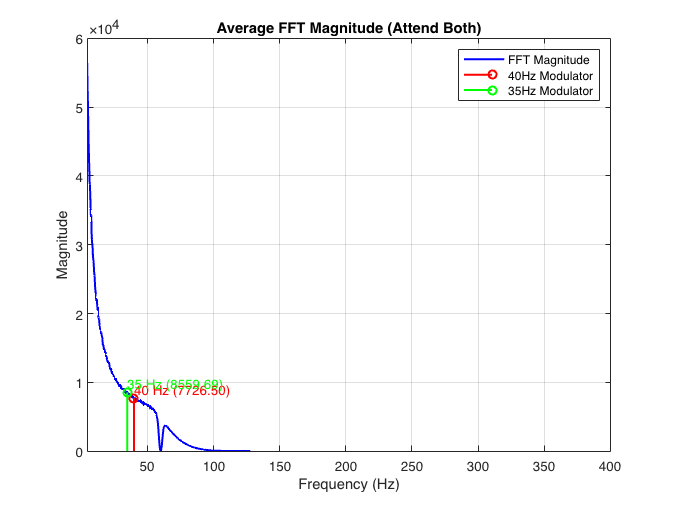

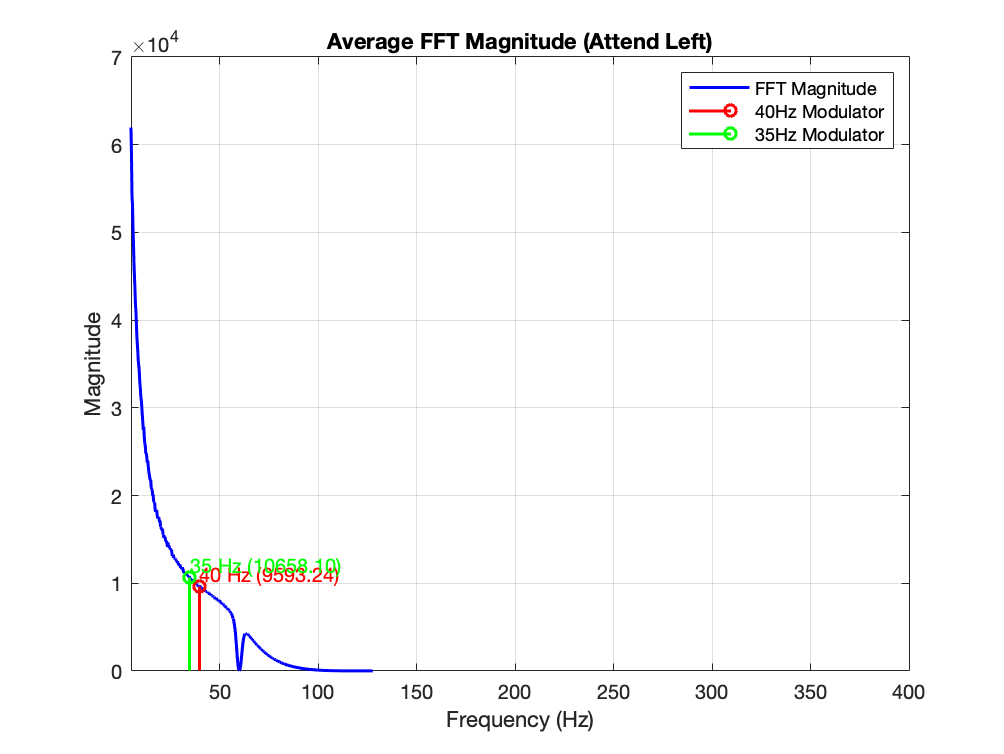

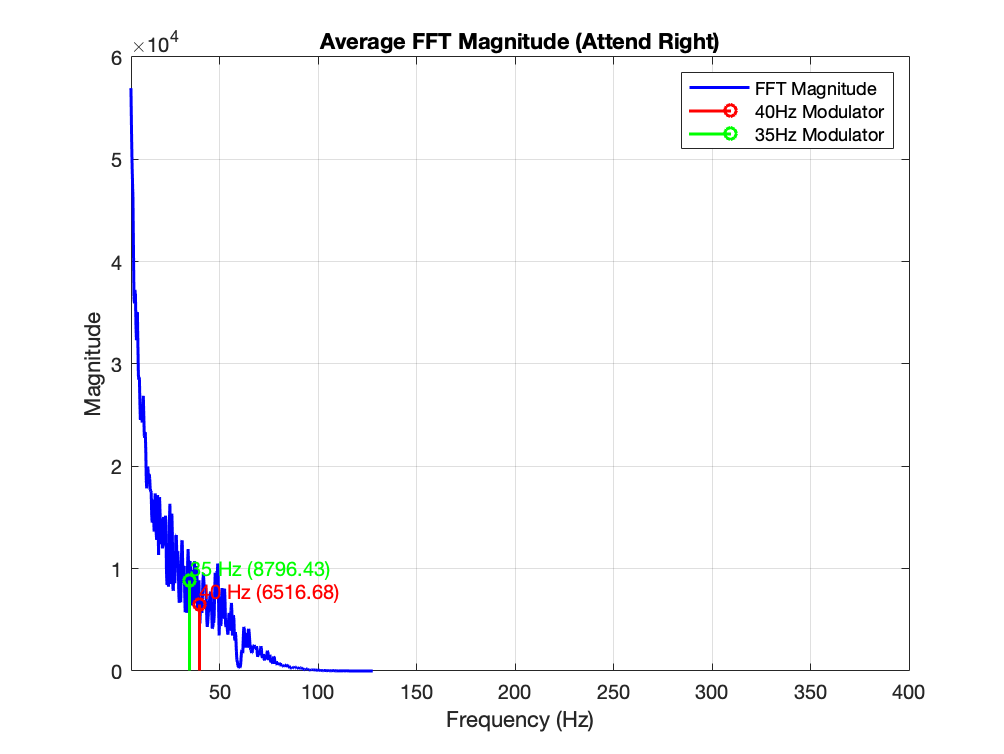

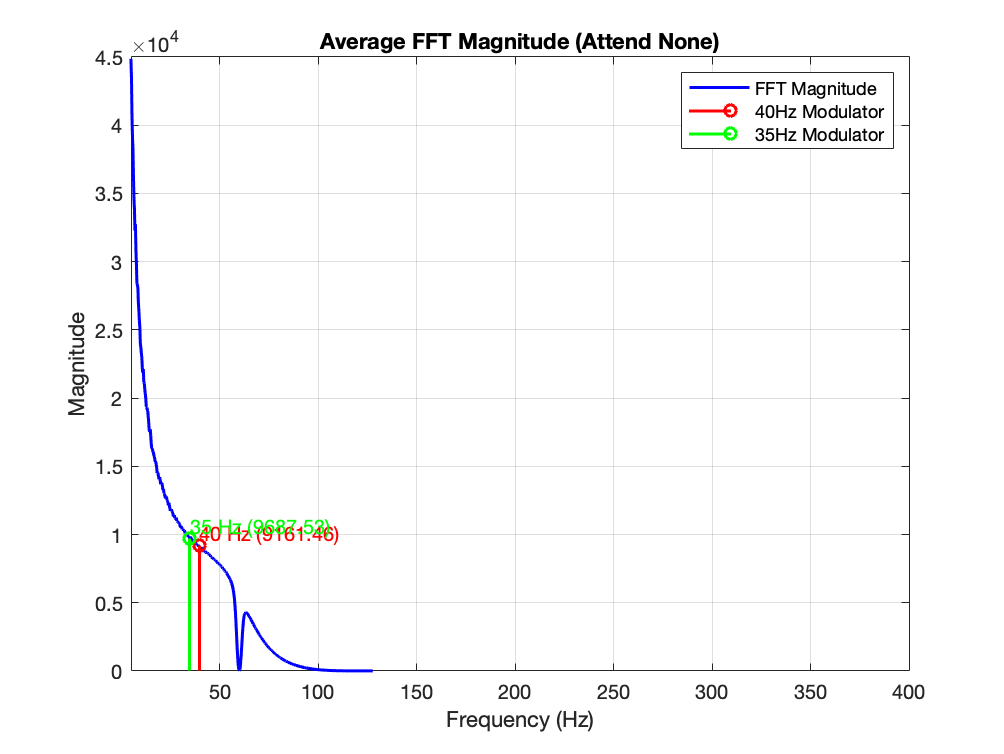


% Conditions to process
conditions = {'Lab7_group5_p1_attend_both_mat', 'Lab7_group5_p1_attend_left_mat', ...
              'Lab7_group5_p1_attend_right_mat', 'Lab7_group5_p1_attend_none_mat'};
titles = {'Attend Both', 'Attend Left', 'Attend Right', 'Attend None'};

% Loop through each condition
for cond_idx = 1:length(conditions)
    % Load the data matrix for the current condition
    data_matrix = loadedData.(conditions{cond_idx}).ans;
    
    % Extract EEG channels (e.g., rows 2 to 8)
    eeg_data = data_matrix(2:8, :);

    % Number of channels
    n_channels = size(eeg_data, 1);

    % Compute FFT for each channel
    fft_magnitudes = zeros(n_channels, nfft / 2); % Preallocate for magnitude of FFT
    for ch = 1:n_channels
        % Compute FFT and keep only positive frequencies
        fft_result = fft(eeg_data(ch, :), nfft); % Full FFT
        fft_magnitudes(ch, :) = abs(fft_result(1:nfft/2)); % Magnitude of positive frequencies
    end

    % Average FFT magnitude over all channels
    avg_fft_magnitude = mean(fft_magnitudes, 1);

    % Plot the average FFT magnitude
    figure;
    plot(freq_vector, avg_fft_magnitude, 'b-', 'LineWidth', 1.5);
    hold on;
    
    % Highlight modulator frequencies
    stem(freq_vector(indices_40Hz), avg_fft_magnitude(indices_40Hz), 'r', 'LineWidth', 1.5);
    stem(freq_vector(indices_35Hz), avg_fft_magnitude(indices_35Hz), 'g', 'LineWidth', 1.5);
    
    % Annotate modulator frequencies
    text(freq_vector(indices_40Hz), avg_fft_magnitude(indices_40Hz), ...
         sprintf('40 Hz (%.2f)', avg_fft_magnitude(indices_40Hz)), ...
         'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left', 'Color', 'r');
    text(freq_vector(indices_35Hz), avg_fft_magnitude(indices_35Hz), ...
         sprintf('35 Hz (%.2f)', avg_fft_magnitude(indices_35Hz)), ...
         'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left', 'Color', 'g');

    % Labels and titles
    title(['Average FFT Magnitude (', titles{cond_idx}, ')']);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    xlim([5, 400]); % Use parentheses for xlim
    legend('FFT Magnitude', '40Hz Modulator', '35Hz Modulator');
    grid on;
    hold off;
end

## Question 5: Create a table or bar graph showing the average magnitude of the ASSR signal over all channels for the two modulator frequencies and for each of the four listening conditions. 

## How do you interpret the data? (6 pts)

- So based on just the average magnitudes the 35Hz is higher for all 4 sessions. I think we shouldn't just predict based on the magnitude of one being bigger than the other. I think the difference between the magnitudes should be past a certain threshold. Especially because simply because the right ear may be dominant it might be skewing the results.

- I also think in this case the attention modulation is weak. The expected effects of attention are not clearly reflected in the data. In the `Attend Left` condition, the 40 Hz response does not dominate, as one might expect if attention were effectively enhancing the left ear response.Similarly, in `Attend Both`, the responses do not converge or balance.

- It seems like we are seeing that when both or none are present they tend to balance each other out more which is expected.

- Overall I would have expected 25Hz to go down in attend left but there may have been experimental error or environmental distruptors,

% Sampling rate
fs = 256; % in Hz
mod_frequencies = [40, 35]; % Modulator frequencies for left and right ear
nfft = 1024; % Number of FFT points

% Conditions to process
conditions = {'Lab7_group5_p1_attend_both_mat', 'Lab7_group5_p1_attend_left_mat', ...
              'Lab7_group5_p1_attend_right_mat', 'Lab7_group5_p1_attend_none_mat'};
titles = {'Attend Both', 'Attend Left', 'Attend Right', 'Attend None'};

% Initialize storage for ASSR magnitudes
assr_magnitudes = zeros(length(conditions), length(mod_frequencies));

% Frequency vector
freq_vector = (0:(nfft/2 - 1)) * (fs / nfft); % Frequency range (0 to Nyquist frequency)

% Loop through each condition
for cond_idx = 1:length(conditions)
    % Load the data matrix for the current condition
    data_matrix = loadedData.(conditions{cond_idx}).ans;
    
    % Extract EEG channels (e.g., rows 2 to 8)
    eeg_data = data_matrix(2:8, :);

    % Number of channels
    n_channels = size(eeg_data, 1);

    % Compute FFT for each channel
    fft_magnitudes = zeros(n_channels, nfft / 2); % Preallocate for magnitude of FFT
    for ch = 1:n_channels
        % Compute FFT and keep only positive frequencies
        fft_result = fft(eeg_data(ch, :), nfft); % Full FFT
        fft_magnitudes(ch, :) = abs(fft_result(1:nfft/2)); % Magnitude of positive frequencies
    end

    % Average FFT magnitude over all channels
    avg_fft_magnitude = mean(fft_magnitudes, 1);

    % Extract FFT magnitudes at the modulator frequencies
    for freq_idx = 1:length(mod_frequencies)
        mod_freq = mod_frequencies(freq_idx);
        mod_index = round(mod_freq * nfft / fs); % Find the corresponding index in the FFT
        assr_magnitudes(cond_idx, freq_idx) = avg_fft_magnitude(mod_index); % Store magnitude
    end
end

% Create a table of results
conditions_column = titles'; % Column with condition names
assr_table = array2table(assr_magnitudes, 'RowNames', conditions_column, ...
                         'VariableNames', {'ASSR_40Hz', 'ASSR_35Hz'});

% Display the table
disp('Average ASSR Magnitudes for Each Condition and Frequency:');

Average ASSR Magnitudes for Each Condition and Frequency:


disp(assr_table);

                    ASSR_40Hz    ASSR_35Hz
                    _________    _________

    Attend Both      7726.5       8559.7  
    Attend Left      9593.2        10658  
    Attend Right     6516.7       8796.4  
    Attend None      9161.5       9687.5  



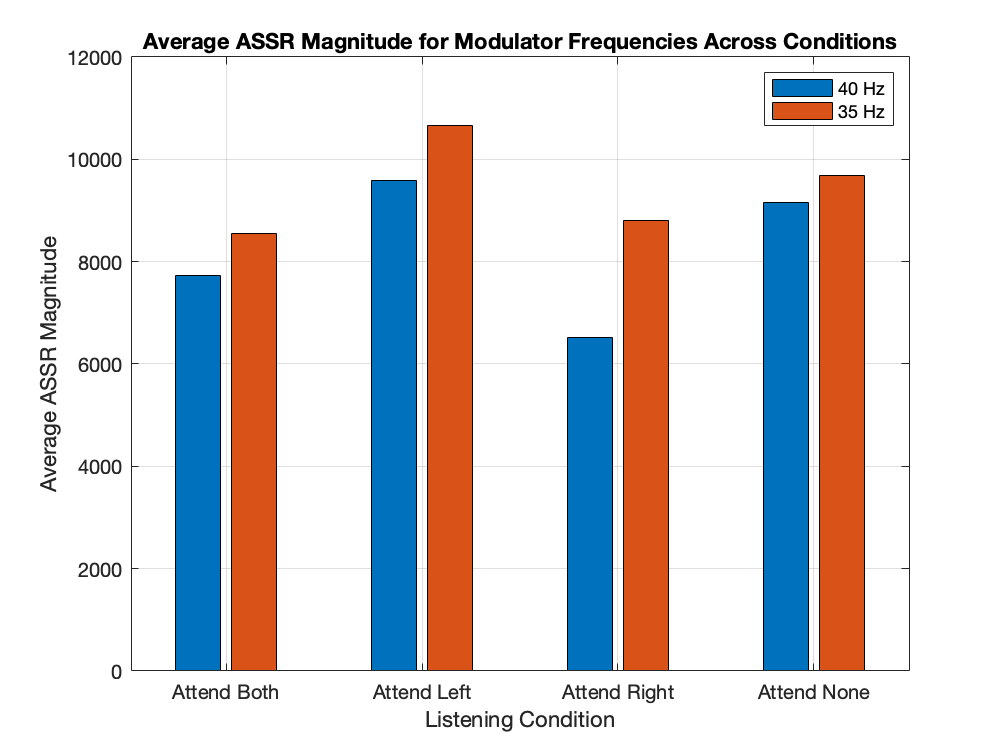


% Create a bar graph
figure;
bar(assr_magnitudes);
xticks(1:length(conditions));
xticklabels(titles);
xlabel('Listening Condition');
ylabel('Average ASSR Magnitude');
legend({'40 Hz', '35 Hz'}, 'Location', 'NorthEast');
title('Average ASSR Magnitude for Modulator Frequencies Across Conditions');
grid on;

## Lab Report Experiment 2: What do you observe? 

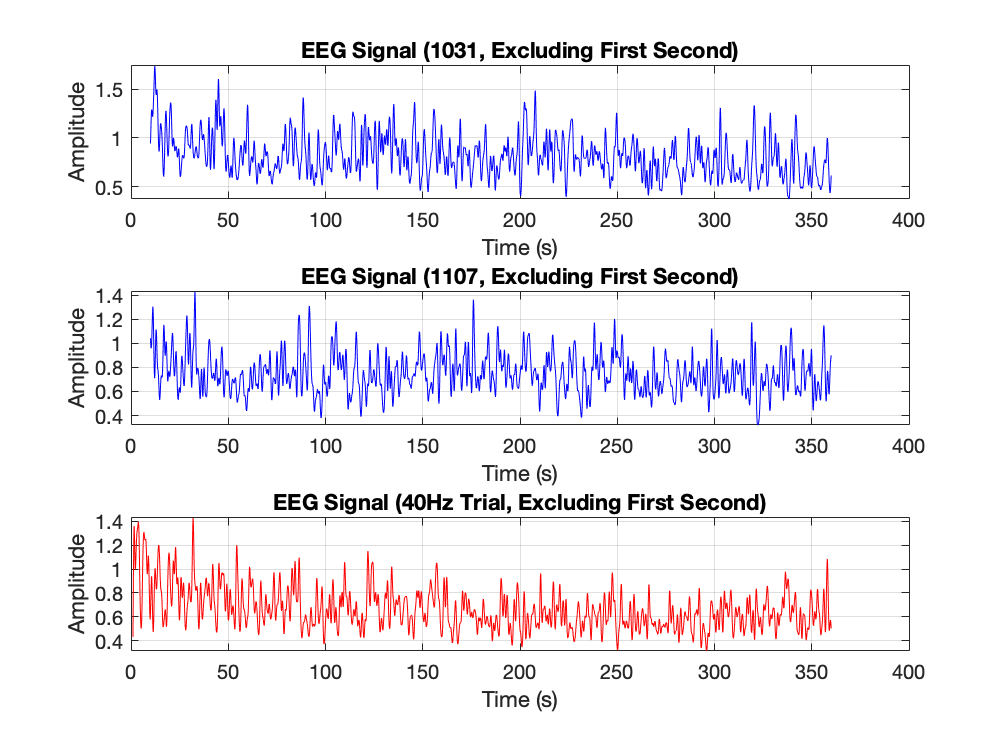


% Load the data
data_1031 = loadedData.Lab7_group5_p2_35hz_1031_mat.ans; % Replace with actual field names
data_1107 = loadedData.Lab7_group5_p2_35hz_1107_mat.ans; 
data_40Hz = loadedData.Lab7_group5_p2_40hz_mat.ans;      % New 40Hz trial data

% Extract time and processed EEG
time_1031 = data_1031(1, :); % First row: time
eeg_1031 = data_1031(2, :);  % Second row: EEG signal

time_1107 = data_1107(1, :); % First row: time
eeg_1107 = data_1107(2, :);  % Second row: EEG signal

time_40Hz = data_40Hz(1, :); % First row: time
eeg_40Hz = data_40Hz(2, :);  % Second row: EEG signal

% Exclude the first 10 seconds
indices_1031 = time_1031 >= 10; % Logical index for time >= 10 seconds
time_1031_filtered = time_1031(indices_1031);
eeg_1031_filtered = eeg_1031(indices_1031);

indices_1107 = time_1107 >= 10; % Logical index for time >= 10 seconds
time_1107_filtered = time_1107(indices_1107);
eeg_1107_filtered = eeg_1107(indices_1107);

indices_40Hz = time_40Hz >= 1; % Logical index for time >= 10 seconds
time_40Hz_filtered = time_40Hz(indices_40Hz);
eeg_40Hz_filtered = eeg_40Hz(indices_40Hz);

% Plot the signals excluding the first 10 seconds
figure;

subplot(3, 1, 1);
plot(time_1031_filtered, eeg_1031_filtered, 'b');
title('EEG Signal (1031, Excluding First Second)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(3, 1, 2);
plot(time_1107_filtered, eeg_1107_filtered, 'b');
title('EEG Signal (1107, Excluding First Second)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(3, 1, 3);
plot(time_40Hz_filtered, eeg_40Hz_filtered, 'r');
title('EEG Signal (40Hz Trial, Excluding First Second)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

## Report the average EEG spectral energy at 40 Hz (amplitude of the envelope) from 100 - 300 seconds after the onset of the experiment. (2 pts)

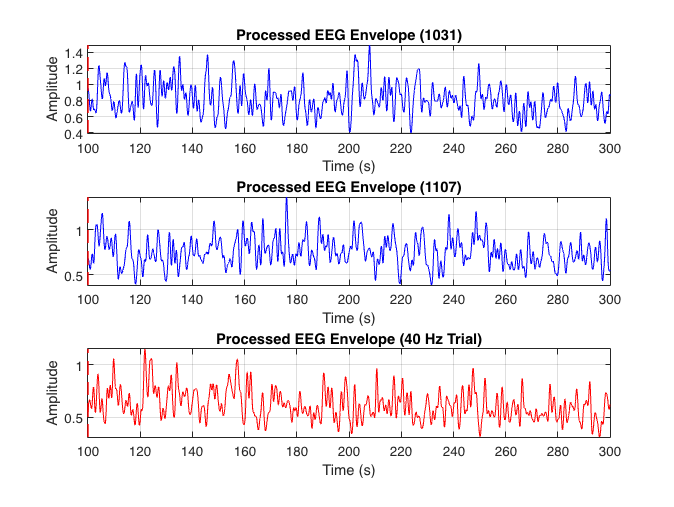

%% Load the data (already preprocessed with bandpass + abs applied)
data_1031 = loadedData.Lab7_group5_p2_35hz_1031_mat.ans; % Replace with actual field names
data_1107 = loadedData.Lab7_group5_p2_35hz_1107_mat.ans;
data_40Hz = loadedData.Lab7_group5_p2_40hz_mat.ans;      % 40 Hz trial data

% Extract time and processed EEG (bandpass + abs applied)
time_1031 = data_1031(1, :); % First row: time
eeg_1031 = data_1031(2, :);  % Second row: processed EEG

time_1107 = data_1107(1, :); % First row: time
eeg_1107 = data_1107(2, :);  % Second row: processed EEG

time_40Hz = data_40Hz(1, :); % First row: time
eeg_40Hz = data_40Hz(2, :);  % Second row: processed EEG

% Define the time range for analysis (0 to 300 seconds)
time_range = [100, 300]; % From experiment start
indices_1031 = (time_1031 >= time_range(1)) & (time_1031 <= time_range(2));
indices_1107 = (time_1107 >= time_range(1)) & (time_1107 <= time_range(2));
indices_40Hz = (time_40Hz >= time_range(1)) & (time_40Hz <= time_range(2));

% Extract the relevant time and EEG data
time_1031_filtered = time_1031(indices_1031);
eeg_1031_filtered = eeg_1031(indices_1031);

time_1107_filtered = time_1107(indices_1107);
eeg_1107_filtered = eeg_1107(indices_1107);

time_40Hz_filtered = time_40Hz(indices_40Hz);
eeg_40Hz_filtered = eeg_40Hz(indices_40Hz);

% Plot the signals for all three datasets
figure;

subplot(3, 1, 1);
plot(time_1031_filtered, eeg_1031_filtered, 'b');
hold on;
xline(100, 'r--', 'LineWidth', 1.5); % Mark 30 seconds (start of tone)
title('Processed EEG Envelope (1031)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(3, 1, 2);
plot(time_1107_filtered, eeg_1107_filtered, 'b');
hold on;
xline(100, 'r--', 'LineWidth', 1.5); % Mark 30 seconds (start of tone)
title('Processed EEG Envelope (1107)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(3, 1, 3);
plot(time_40Hz_filtered, eeg_40Hz_filtered, 'r');
hold on;
xline(100, 'r--', 'LineWidth', 1.5); % Mark 30 seconds (start of tone)
title('Processed EEG Envelope (40 Hz Trial)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;


% Highlight key observations in console output
fprintf('Key Observations:\n');

Key Observations:


fprintf('- EEG signal visualized for 0 to 300 seconds.\n');

- EEG signal visualized for 0 to 300 seconds.


fprintf('- Red dashed line indicates the onset of the 40 Hz modulated tone (30 seconds).\n');

- Red dashed line indicates the onset of the 40 Hz modulated tone (30 seconds).



% Compute average amplitude for each dataset after 30 seconds
avg_1031_after_100 = mean(eeg_1031_filtered(time_1031_filtered >= 100));
avg_1107_after_100 = mean(eeg_1107_filtered(time_1107_filtered >= 100));
avg_40Hz_after_100 = mean(eeg_40Hz_filtered(time_40Hz_filtered >= 100));

% Display average values in the console
fprintf('Average Amplitude (30 to 300 seconds):\n');

Average Amplitude (30 to 300 seconds):


fprintf(' - Dataset 1031: %.4f\n', avg_1031_after_100);

 - Dataset 1031: 0.8186


fprintf(' - Dataset 1107: %.4f\n', avg_1107_after_100);

 - Dataset 1107: 0.7550


fprintf(' - Dataset 40Hz: %.4f\n', avg_40Hz_after_100);

 - Dataset 40Hz: 0.6209




% Highlight key observations in console output
fprintf('Key Observations:\n');

Key Observations:


fprintf('- EEG signal visualized for 0 to 300 seconds.\n');

- EEG signal visualized for 0 to 300 seconds.


fprintf('- Red dashed line indicates the onset of the 40 Hz modulated tone (30 seconds).\n');

- Red dashed line indicates the onset of the 40 Hz modulated tone (30 seconds).


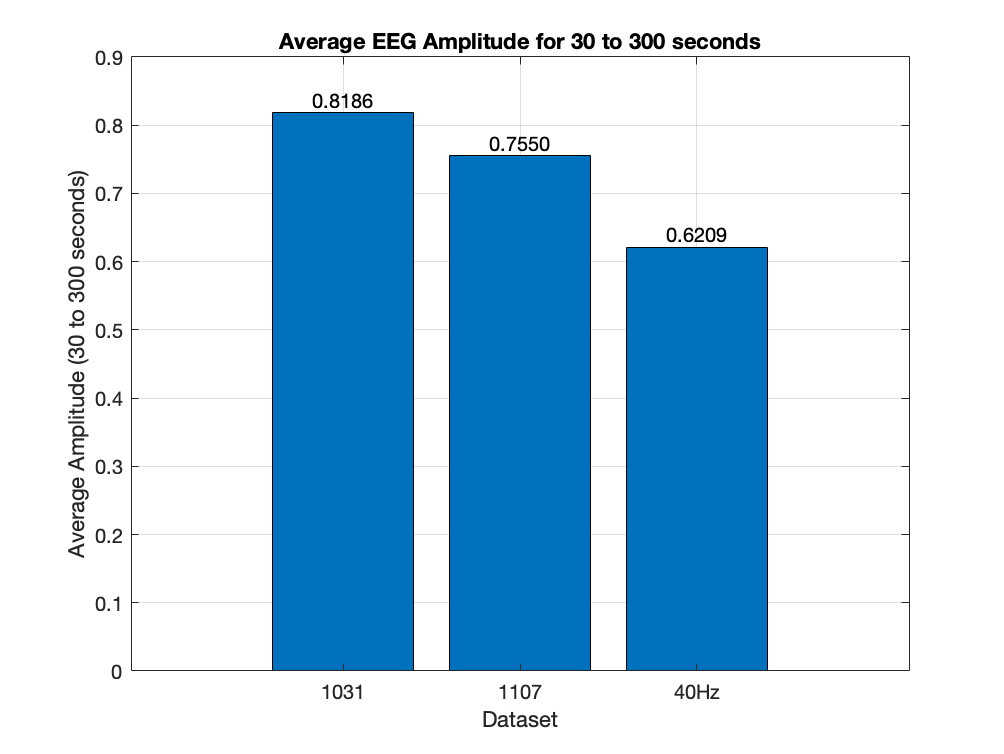




% Bar graph data
datasets = {'1031', '1107', '40Hz'};
average_amplitudes = [avg_1031_after_30, avg_1107_after_30, avg_40Hz_after_30];

% Plot the bar graph
figure;
bar(average_amplitudes);
xticks(1:length(datasets));
xticklabels(datasets);
xlabel('Dataset');
ylabel('Average Amplitude (30 to 300 seconds)');
title('Average EEG Amplitude for 30 to 300 seconds');
grid on;

% Add values on top of the bars
for i = 1:length(average_amplitudes)
    text(i, average_amplitudes(i), sprintf('%.4f', average_amplitudes(i)), ...
         'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
end

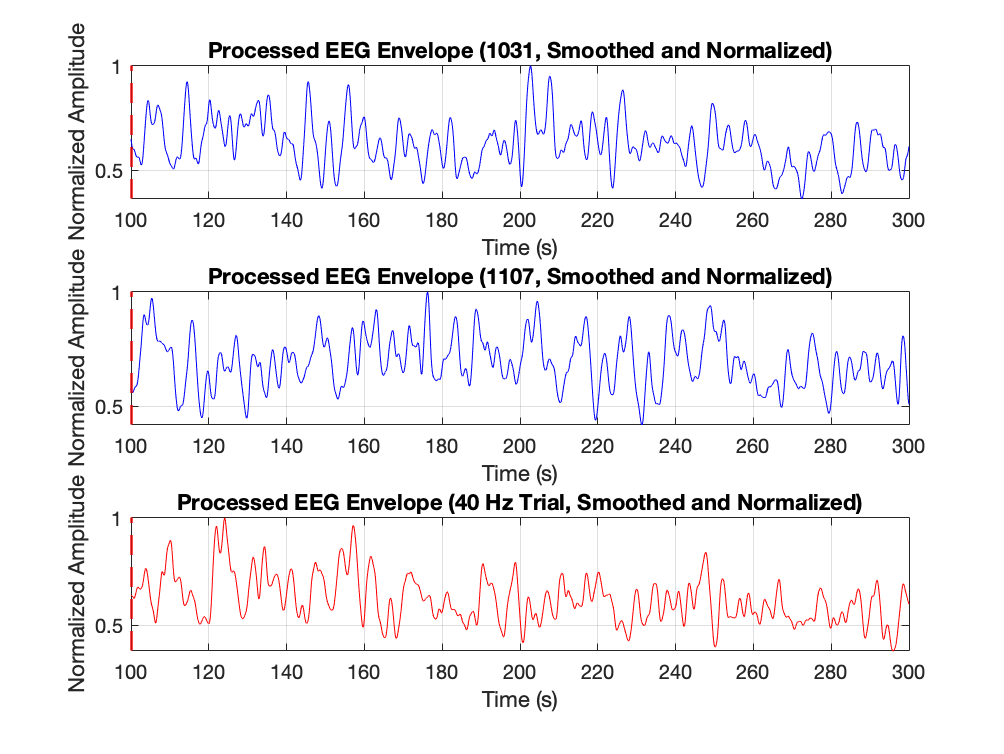

% Load the data (already preprocessed with bandpass + abs applied)
data_1031 = loadedData.Lab7_group5_p2_35hz_1031_mat.ans; % Replace with actual field names
data_1107 = loadedData.Lab7_group5_p2_35hz_1107_mat.ans;
data_40Hz = loadedData.Lab7_group5_p2_40hz_mat.ans;      % 40 Hz trial data

% Extract time and processed EEG (bandpass + abs applied)
time_1031 = data_1031(1, :); % First row: time
eeg_1031 = data_1031(2, :);  % Second row: processed EEG

time_1107 = data_1107(1, :); % First row: time
eeg_1107 = data_1107(2, :);  % Second row: processed EEG

time_40Hz = data_40Hz(1, :); % First row: time
eeg_40Hz = data_40Hz(2, :);  % Second row: processed EEG

% Define the time range for analysis (100 to 300 seconds)
time_range = [100, 300]; % From experiment start
indices_1031 = (time_1031 >= time_range(1)) & (time_1031 <= time_range(2));
indices_1107 = (time_1107 >= time_range(1)) & (time_1107 <= time_range(2));
indices_40Hz = (time_40Hz >= time_range(1)) & (time_40Hz <= time_range(2));

% Extract the relevant time and EEG data
time_1031_filtered = time_1031(indices_1031);
eeg_1031_filtered = eeg_1031(indices_1031);

time_1107_filtered = time_1107(indices_1107);
eeg_1107_filtered = eeg_1107(indices_1107);

time_40Hz_filtered = time_40Hz(indices_40Hz);
eeg_40Hz_filtered = eeg_40Hz(indices_40Hz);

% Apply smoothing (moving average filter)
window_size = 400; % Number of samples for the moving average (adjust as needed)
eeg_1031_smoothed = movmean(eeg_1031_filtered, window_size);
eeg_1107_smoothed = movmean(eeg_1107_filtered, window_size);
eeg_40Hz_smoothed = movmean(eeg_40Hz_filtered, window_size);

% Normalize the signals (divide by max amplitude)
eeg_1031_normalized = eeg_1031_smoothed / max(eeg_1031_smoothed);
eeg_1107_normalized = eeg_1107_smoothed / max(eeg_1107_smoothed);
eeg_40Hz_normalized = eeg_40Hz_smoothed / max(eeg_40Hz_smoothed);

% Plot the signals for all three datasets
figure;

subplot(3, 1, 1);
plot(time_1031_filtered, eeg_1031_normalized, 'b');
hold on;
xline(100, 'r--', 'LineWidth', 1.5); % Mark 100 seconds
title('Processed EEG Envelope (1031, Smoothed and Normalized)');
xlabel('Time (s)');
ylabel('Normalized Amplitude');
grid on;

subplot(3, 1, 2);
plot(time_1107_filtered, eeg_1107_normalized, 'b');
hold on;
xline(100, 'r--', 'LineWidth', 1.5); % Mark 100 seconds
title('Processed EEG Envelope (1107, Smoothed and Normalized)');
xlabel('Time (s)');
ylabel('Normalized Amplitude');
grid on;

subplot(3, 1, 3);
plot(time_40Hz_filtered, eeg_40Hz_normalized, 'r');
hold on;
xline(100, 'r--', 'LineWidth', 1.5); % Mark 100 seconds
title('Processed EEG Envelope (40 Hz Trial, Smoothed and Normalized)');
xlabel('Time (s)');
ylabel('Normalized Amplitude');
grid on;

## What is the difference between the average value of the EEG spectral energy at 35Hz versus 40Hz?



% Define the time range for analysis
time_range = [30, 300]; % After 30 seconds
indices_1031 = (time_1031 >= time_range(1)) & (time_1031 <= time_range(2));
indices_1107 = (time_1107 >= time_range(1)) & (time_1107 <= time_range(2));

% Compute average spectral energy at 35Hz and 40Hz
avg_35Hz_1031 = mean(eeg_35Hz_1031(indices_1031));
avg_40Hz_1031 = mean(eeg_40Hz_1031(indices_1031));

avg_35Hz_1107 = mean(eeg_35Hz_1107(indices_1107));
avg_40Hz_1107 = mean(eeg_40Hz_1107(indices_1107));

% Compute differences
difference_1031 = avg_40Hz_1031 - avg_35Hz_1031;
difference_1107 = avg_40Hz_1107 - avg_35Hz_1107;

% Display results
fprintf('Difference in EEG Spectral Energy (40 Hz - 35 Hz):\n');

Difference in EEG Spectral Energy (40 Hz - 35 Hz):


fprintf(' - Dataset 1031: %.4f\n', difference_1031);

 - Dataset 1031: 0.1742


fprintf(' - Dataset 1107: %.4f\n', difference_1107);

 - Dataset 1107: 0.2491


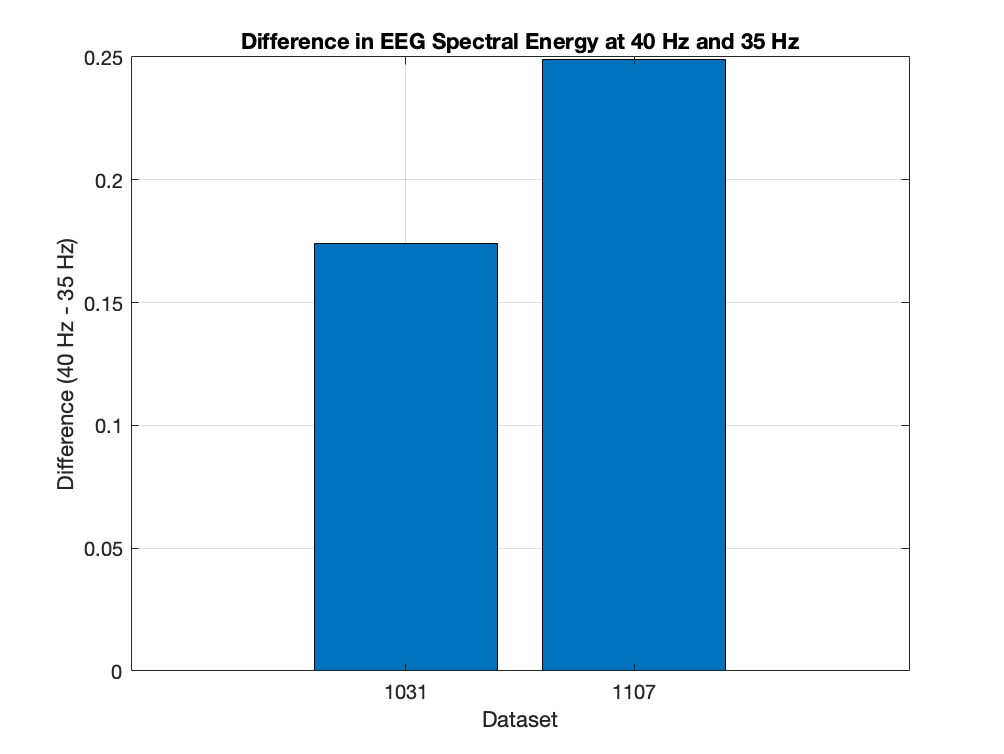


% OPTIONAL: Visualize the differences
differences = [difference_1031, difference_1107];
figure;
bar(differences);
xticks(1:2);
xticklabels({'1031', '1107'});
ylabel('Difference (40 Hz - 35 Hz)');
xlabel('Dataset');
title('Difference in EEG Spectral Energy at 40 Hz and 35 Hz');
grid on;

## Why do you find different frequencies of the spectral energy for each experimental condition?

## Which condition produces greater magnitude?

## Does this finding match your observation from the previous experiment? (4 pts)

## Experiment 3 Report: Explain the calculation of your threshold.

a. First find the average ratios (saved in .mat file) for each attentional case.

b. Do not include the first 60 seconds in your analysis.

c. Take the mean value of the averaged ratios. This is the threshold.

d. Modify your model to compare the ratio with the appropriate threshold.

You can use “Compare to Constant” block


% Load the dataset
data = loadedData.Lab7_group5_p3_mat.ans;

% Extract relevant rows
time = data(1, :);        % Row 1: Time
ratios = data(2, :);      % Row 2: Ratios

% Define analysis range
start_time = 60; % Exclude the first 60 seconds
analysis_indices = time > start_time; % Logical indices for analysis range

% Filter data to exclude the first 60 seconds
time_filtered = time(analysis_indices);
ratios_filtered = ratios(analysis_indices);

% Define 60-second intervals starting from 60 seconds
interval_length = 60; % in seconds
max_time = max(time_filtered); % Maximum time in the filtered data
num_intervals = floor((max_time - start_time) / interval_length);

% Initialize storage for average ratios in each interval
average_ratios = zeros(1, num_intervals);

% Calculate average ratios for each 60-second interval
for i = 1:num_intervals
    interval_start = start_time + (i - 1) * interval_length;
    interval_end = interval_start + interval_length;

    % Find indices corresponding to the current interval
    interval_indices = (time_filtered >= interval_start) & (time_filtered < interval_end);

    % Calculate the average ratio for this interval
    average_ratios(i) = mean(ratios_filtered(interval_indices));
end

% Calculate the threshold
threshold = mean(average_ratios);

% Display the results
disp('Average Ratios for Each 60-Second Interval:');

Average Ratios for Each 60-Second Interval:


disp(array2table(average_ratios', 'VariableNames', {'AverageRatio'}, ...
    'RowNames', arrayfun(@(x) sprintf('Interval_%d', x), 1:num_intervals, 'UniformOutput', false)));

                  AverageRatio
                  ____________

    Interval_1      0.88069   
    Interval_2      0.94233   
    Interval_3         1.02   
    Interval_4      0.97475   
    Interval_5       0.8991   



fprintf('Threshold (Mean of Averaged Ratios): %.4f\n', threshold);

Threshold (Mean of Averaged Ratios): 0.9434


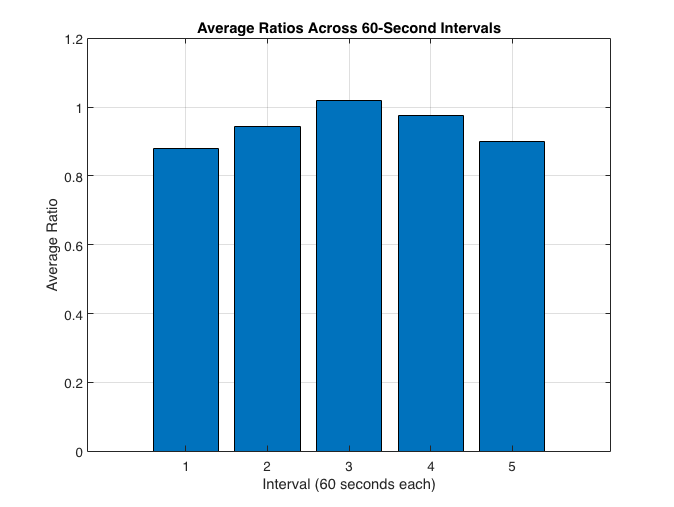


% Visualization of average ratios across intervals
figure;
bar(1:num_intervals, average_ratios);
xlabel('Interval (60 seconds each)');
ylabel('Average Ratio');
title('Average Ratios Across 60-Second Intervals');
grid on;

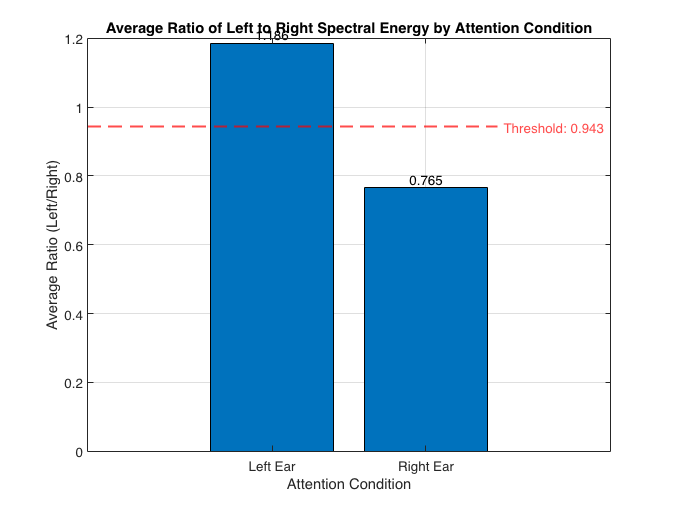

% Load the dataset
data = loadedData.Lab7_group5_p3_mat.ans;

% Extract relevant rows
time = data(1, :);        % Row 1: Time
ratios = data(2, :);      % Row 2: Ratios

% Define the threshold for Left vs Right
threshold = 0.9434; % Example threshold from earlier

% Classify conditions based on threshold
attention_conditions = ratios > threshold; % Logical: 1 = Left Ear, 0 = Right Ear

% Calculate average ratio for each condition
average_left_ratio = mean(ratios(attention_conditions));  % Average for Left Ear
average_right_ratio = mean(ratios(~attention_conditions)); % Average for Right Ear

% Bar Plot
figure;
bar_data = [average_left_ratio, average_right_ratio];
bar_labels = {'Left Ear', 'Right Ear'};
bar(bar_data, 'FaceColor', 'flat');

% Customize the plot
set(gca, 'XTickLabel', bar_labels);
xlabel('Attention Condition');
ylabel('Average Ratio (Left/Right)');
title('Average Ratio of Left to Right Spectral Energy by Attention Condition');
grid on;

% Add values on top of bars
text(1:length(bar_data), bar_data, num2str(bar_data', '%.3f'), ...
     'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'center');

% Add a red threshold line
hold on;
yline(threshold, 'r--', 'LineWidth', 1.5, 'Label', sprintf('Threshold: %.3f', threshold), ...
      'LabelHorizontalAlignment', 'right', 'LabelVerticalAlignment', 'middle');
hold off;


% Print threshold value to the console
fprintf('Threshold (red line): %.3f\n', threshold);

Threshold (red line): 0.943


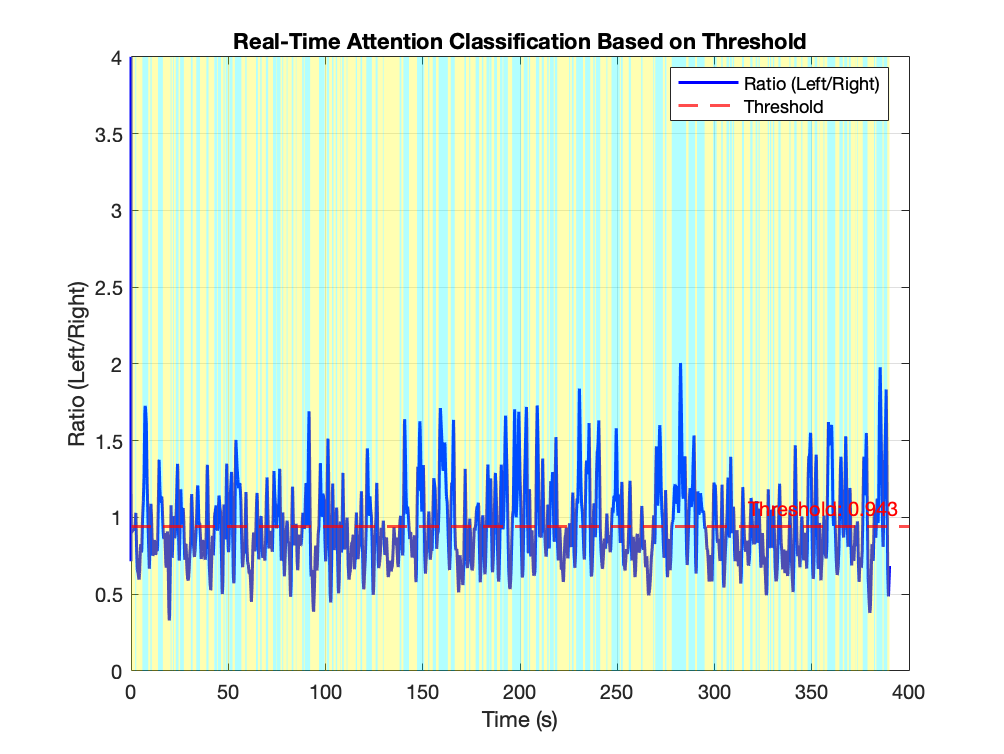


% Load the dataset
data = loadedData.Lab7_group5_p3_mat.ans;

% Extract relevant rows
time = data(1, :);        % Row 1: Time
ratios = data(2, :);      % Row 2: Ratios
threshold = 0.9434;       % Threshold from previous calculation

% Classify attention states
attention_states = ratios > threshold; % Logical: 1 = Left Ear, 0 = Right Ear

% Initialize variables for shading
state_start_idx = 1; % Start index of a state
current_state = attention_states(1); % Initial state (Left or Right)

% Plot the ratio over time
figure;
plot(time, ratios, 'b-', 'LineWidth', 1.5); % Plot the ratio
hold on;
yline(threshold, 'r--', 'LineWidth', 1.5, 'Label', sprintf('Threshold: %.3f', threshold));

% Loop to shade background for attention states
for i = 2:length(attention_states)
    if attention_states(i) ~= current_state || i == length(attention_states)
        % End of the current state
        state_end_idx = i - 1; % End index of the current state
        if i == length(attention_states)
            state_end_idx = i; % Include the last index if at the end
        end
        
        % Get the time range for the current state
        start_time = time(state_start_idx);
        end_time = time(state_end_idx);

        % Shade based on the current state
        if current_state
            % Left Ear (shade light blue)
            fill([start_time, end_time, end_time, start_time], [0, 0, max(ratios), max(ratios)], ...
                 'cyan', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
        else
            % Right Ear (shade light yellow)
            fill([start_time, end_time, end_time, start_time], [0, 0, max(ratios), max(ratios)], ...
                 'yellow', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
        end

        % Update for the next state
        state_start_idx = i;
        current_state = attention_states(i);
    end
end

% Finalize plot
xlabel('Time (s)');
ylabel('Ratio (Left/Right)');
title('Real-Time Attention Classification Based on Threshold');
legend('Ratio (Left/Right)', 'Threshold', 'Location', 'Best');
ylim([0, 4]); % Adjust Y-axis for better visualization
grid on;
hold off;